clc;
close all;
clear;

## 创建障碍物和起讫点位置

% 障碍物数量
num = 50;  

% 随机生成 X、Y、Z 坐标和大小
obstacle = [rand(num, 1) * 10, rand(num, 1) * 10, rand(num, 1) * 10];

% 创建初始位置和目标位置
start = [0 0 0];
goal = [10 10 10];

## 生成并绘制避障路径

path = APF3D(start, goal, obstacle);

## 绘制地图

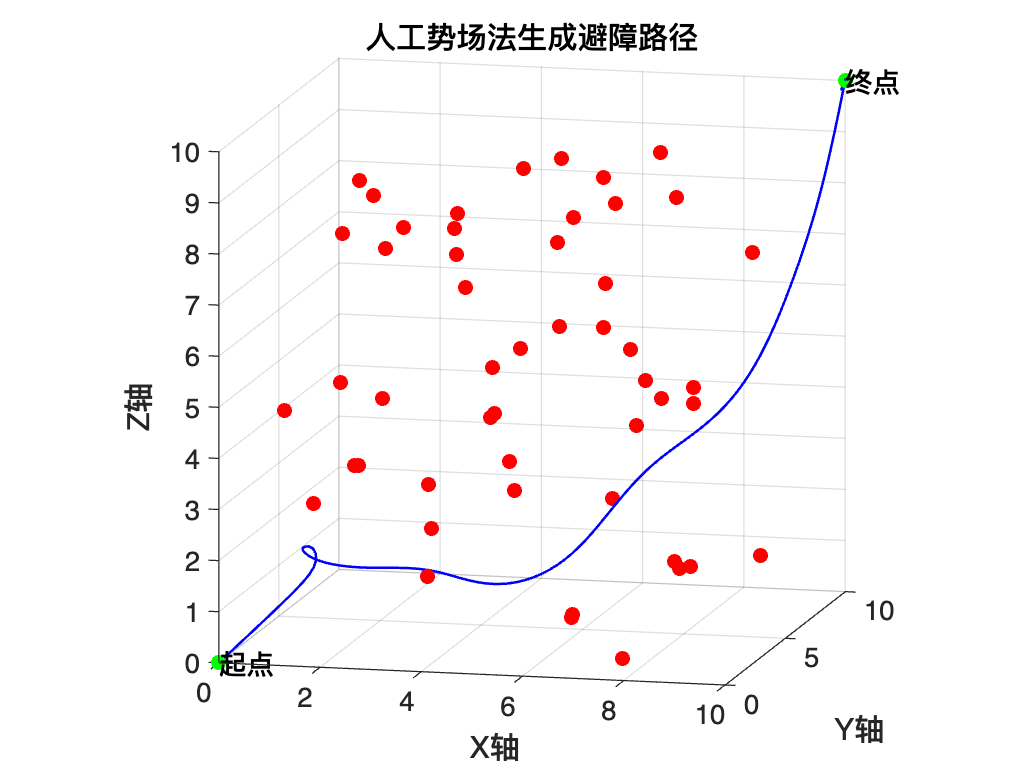

% 绘制三维散点图
figure();
scatter3(obstacle(:,1), obstacle(:,2), obstacle(:,3), 'r', 'filled');

xlabel('X轴'); ylabel('Y轴'); zlabel('Z轴'); title('人工势场法生成避障路径');

grid on;
axis equal;

hold on;
scatter3(start(1),start(2),start(3),'filled','g');
text(start(1),start(2),start(3),'起点');
scatter3(goal(1),goal(2),goal(3),'filled','g');
text(goal(1),goal(2),goal(3),'终点');

plot3(path(:,1),path(:,2),path(:,3),'LineWidth',1,'Color','b');